clc; clear; close all;
addpath PROPACK;

% Load RGB figure
% image = imread('tree.jpg');
image = imread('house.png');

% Normalize R, G, and B channels, respectively
image_double = double(image);
img_R = image_double(:,:,1); img_G = image_double(:,:,2); img_B = image_double(:,:,3);
xm_R = min(img_R(:)); Io_R = img_R-xm_R; img_R = Io_R/max(Io_R(:));
xm_G = min(img_G(:)); Io_G = img_G-xm_G; img_G = Io_G/max(Io_G(:));
xm_B = min(img_B(:)); Io_B = img_B-xm_B; img_B = Io_B/max(Io_B(:));

% Parameters setting
[nx,ny,~] = size(image_double);
tol = 1e-4;      % stopping criteria
maxIter = 1000;  % maximum allowable iterations

% % frobenius norm for RE
% img_R_fro = norm(img_R, 'fro');
% img_G_fro = norm(img_G, 'fro');
% img_B_fro = norm(img_B, 'fro');
% 
% % psnr
% psnr_subted = 3 * 10*log10(255*255*nx*ny);

% normalized image
norm_img = cat(3, img_R, img_G, img_B);

% frobenius norm for normalized image
norm_img_fro = norm(norm_img, 'fro');
img_dou_fro = norm(image_double, 'fro');

% psnr
psnr_subted = 10*log10(nx*ny*255*255);

% Random mask
mask = zeros(nx,ny); samp_rate = 0.7;  % sampling rate
chosen = randperm(nx*ny,round(samp_rate*nx*ny)); mask(chosen) = 1 ;

% Masked image
mask_R = img_R.*mask; mask_G = img_G.*mask; mask_B = img_B.*mask;
mask_image = cat(3,mask_R,mask_G,mask_B);

## SVT

tao = sqrt(nx*ny); step = 1.2*samp_rate;
SVT_recon_R = SVT(mask_R,mask,tao,step,maxIter,tol);
SVT_recon_R1 = SVT_recon_R * max(Io_R(:)) + xm_R;
SVT_recon_G = SVT(mask_G,mask,tao,step,maxIter,tol);
SVT_recon_G1 = SVT_recon_G * max(Io_G(:)) + xm_G;
SVT_recon_B = SVT(mask_B,mask,tao,step,maxIter,tol);
SVT_recon_B1 = SVT_recon_B * max(Io_B(:)) + xm_B;
SVT_image = cat(3,SVT_recon_R,SVT_recon_G,SVT_recon_B);
SVT_image1 = cat(3,SVT_recon_R1,SVT_recon_G1,SVT_recon_B1);

% % ||X* - X||_F
% svt_diff_fro_R = norm(SVT_recon_R - img_R, 'fro');
% svt_diff_fro_G = norm(SVT_recon_G - img_G, 'fro');
% svt_diff_fro_B = norm(SVT_recon_B - img_B, 'fro');

% % RE
% svt_re = svt_diff_fro_R/img_R_fro + svt_diff_fro_G/img_G_fro + svt_diff_fro_B/img_B_fro
% % PSNR
% svt_psnr = psnr_subted - 20*(log10(svt_diff_fro_R) + log10(svt_diff_fro_G) + log10(svt_diff_fro_B))

% ||X* - X||_F
svt_diff_fro = norm(SVT_image1 - image_double, 'fro');

% re
svt_re =  svt_diff_fro / img_dou_fro

svt_re = 0.0399

% psnr
% svt_psnr = psnr_subted - 20*log10(svt_diff_fro)
svt_psnr = psnr(SVT_image1, image_double)

svt_psnr = 34.9890

## Sp_lp

gamma = 1; p1 = 0.1; p2 = 0.1;
Sp_lp_new_recon_R = Sp_lp_new(mask_R,mask,gamma,p1,p2,maxIter,tol);
Sp_lp_new_recon_R1 = Sp_lp_new_recon_R * max(Io_R(:)) + xm_R;
Sp_lp_new_recon_G = Sp_lp_new(mask_G,mask,gamma,p1,p2,maxIter,tol);
Sp_lp_new_recon_G1 = Sp_lp_new_recon_G * max(Io_G(:)) + xm_G;
Sp_lp_new_recon_B = Sp_lp_new(mask_B,mask,gamma,p1,p2,maxIter,tol);
Sp_lp_new_recon_B1 = Sp_lp_new_recon_B * max(Io_B(:)) + xm_B;
Sp_lp_new_image = cat(3,Sp_lp_new_recon_R,Sp_lp_new_recon_G,Sp_lp_new_recon_B);
Sp_lp_new_image1 = cat(3,Sp_lp_new_recon_R1,Sp_lp_new_recon_G1,Sp_lp_new_recon_B1);

% % ||X* - X||_F
% splp_diff_fro_R = norm(Sp_lp_new_recon_R - img_R, 'fro');
% splp_diff_fro_G = norm(Sp_lp_new_recon_G - img_G, 'fro');
% splp_diff_fro_B = norm(Sp_lp_new_recon_B - img_B, 'fro');
% 
% % RE
% splp_re = splp_diff_fro_R/img_R_fro + splp_diff_fro_G/img_G_fro + splp_diff_fro_B/img_B_fro
% % PSNR
% splp_psnr = psnr_subted - 20*(log10(splp_diff_fro_R) + log10(splp_diff_fro_G) + log10(splp_diff_fro_B))

% ||X* - X||_F
splp_diff_fro = norm(Sp_lp_new_image1 - image_double, 'fro');

% re
splp_re =  splp_diff_fro / img_dou_fro

splp_re = 0.0443

% psnr
% splp_psnr = psnr_subted - 20*log10(splp_diff_fro)
splp_psnr = psnr(Sp_lp_new_image1, image_double)

splp_psnr = 36.1670

## WNNM

C = sqrt(nx * ny);
[wnnm_recon_r, ~] = WNNM(mask_R, mask, C, eps, maxIter, tol);
wnnm_recon_r1 = wnnm_recon_r * max(Io_R(:)) + xm_R;
[wnnm_recon_g, ~] = WNNM(mask_G, mask, C, eps, maxIter, tol);
wnnm_recon_g1 = wnnm_recon_g * max(Io_G(:)) + xm_G;
[wnnm_recon_b, ~] = WNNM(mask_B, mask, C, eps, maxIter, tol);
wnnm_recon_b1 = wnnm_recon_b * max(Io_B(:)) + xm_B;
wnnm_image = cat(3, wnnm_recon_r, wnnm_recon_g, wnnm_recon_b);
wnnm_image1 = cat(3, wnnm_recon_r1, wnnm_recon_g1, wnnm_recon_b1);

% % ||X* - X||_F
% wnnm_diff_fro_R = norm(wnnm_recon_r - img_R, 'fro');
% wnnm_diff_fro_G = norm(wnnm_recon_g - img_G, 'fro');
% wnnm_diff_fro_B = norm(wnnm_recon_b - img_B, 'fro');
% 
% % RE
% wnnm_re = wnnm_diff_fro_R/img_R_fro + wnnm_diff_fro_G/img_G_fro + wnnm_diff_fro_B/img_B_fro
% % PSNR
% wnnm_psnr = psnr_subted - 20*(log10(wnnm_diff_fro_R) + log10(wnnm_diff_fro_G) + log10(wnnm_diff_fro_B))

% ||X* - X||_F
wnnm_diff_fro = norm(wnnm_image1 - image_double, 'fro');

% re
wnnm_re =  wnnm_diff_fro / img_dou_fro

wnnm_re = 0.0429

% psnr
% wnnm_psnr = psnr_subted - 20*log10(wnnm_diff_fro)
wnnm_psnr = psnr(wnnm_image1, image_double)

wnnm_psnr = 36.3712

## N/F

lembda = 3; mu1 = 0.01; mu2 = 0.01; k_max = 100; t_max = 5; tol_nf = 1e-5;
nf_r = NF(mask_R, mask, lembda, mu1, mu2, k_max, t_max, tol_nf);
nf_r1 = nf_r * max(Io_R(:)) + xm_R;
nf_g = NF(mask_G, mask, lembda, mu1, mu2, k_max, t_max, tol_nf);
nf_g1 = nf_g * max(Io_G(:)) + xm_G;
nf_b = NF(mask_B, mask, lembda, mu1, mu2, k_max, t_max, tol_nf);
nf_b1 = nf_b * max(Io_B(:)) + xm_B;
nf_image = cat(3, nf_r, nf_g, nf_b);
nf_image1 = cat(3, nf_r1, nf_g1, nf_b1);

% % ||X* - X||_F
% nf_diff_fro_R = norm(nf_r - img_R, 'fro');
% nf_diff_fro_G = norm(nf_g - img_G, 'fro');
% nf_diff_fro_B = norm(nf_b - img_B, 'fro');
% 
% % RE
% nf_re = nf_diff_fro_R/img_R_fro + nf_diff_fro_G/img_G_fro + nf_diff_fro_B/img_B_fro
% % PSNR
% nf_psnr = psnr_subted - 20*(log10(nf_diff_fro_R) + log10(nf_diff_fro_G) + log10(nf_diff_fro_B))

% ||X* - X||_F
nf_diff_fro = norm(nf_image1 - image_double, 'fro');

% re
nf_re =  nf_diff_fro / img_dou_fro

nf_re = 0.0321

% psnr
% nf_psnr = psnr_subted - 20*log10(nf_diff_fro)
nf_psnr = psnr(nf_image1, image_double)

nf_psnr = 37.1108

## Figure

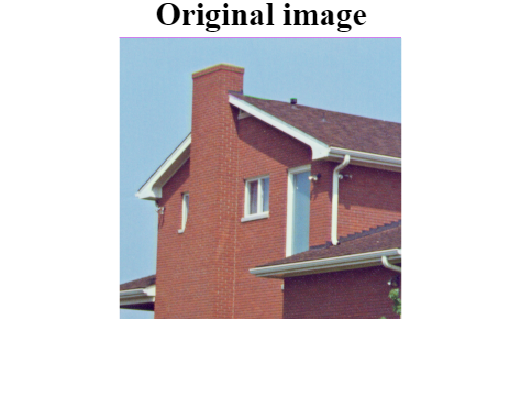

figure; imshow(image,[]); title('Original image','FontSize',15,'FontName','Times New Roman');

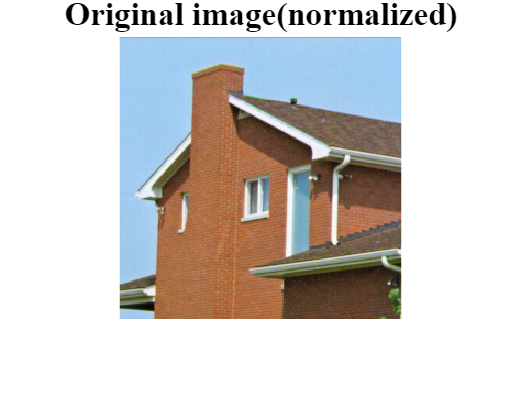

figure; imshow(norm_img,[]); title('Original image(normalized)','FontSize',15,'FontName','Times New Roman');

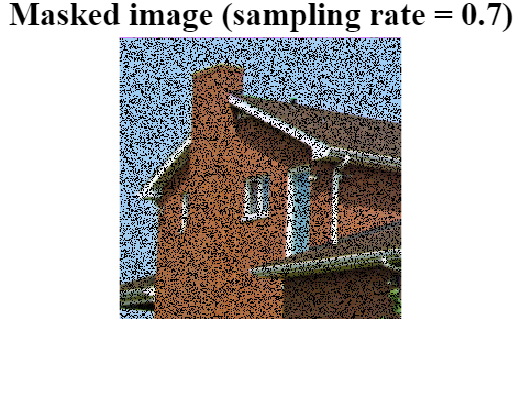

figure; imshow(mask_image,[]); title(['Masked image (sampling rate = ', num2str(samp_rate),')'],'FontSize',15,'FontName','Times New Roman');

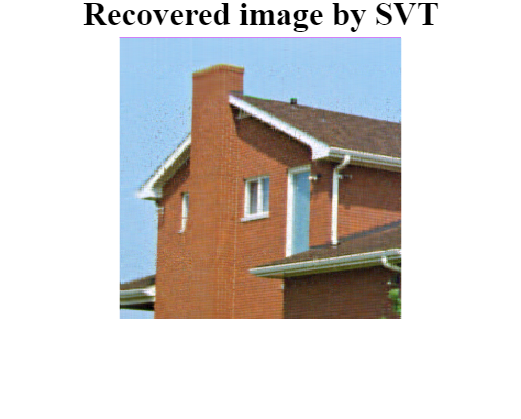

figure; imshow(SVT_image,[]); title('Recovered image by SVT','FontSize',15,'FontName','Times New Roman');

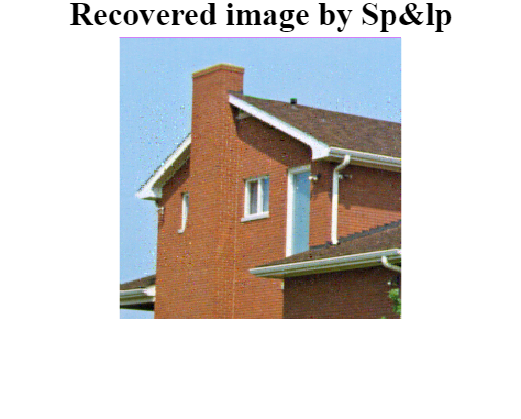

figure; imshow(Sp_lp_new_image,[]); title('Recovered image by Sp&lp','FontSize',15,'FontName','Times New Roman');

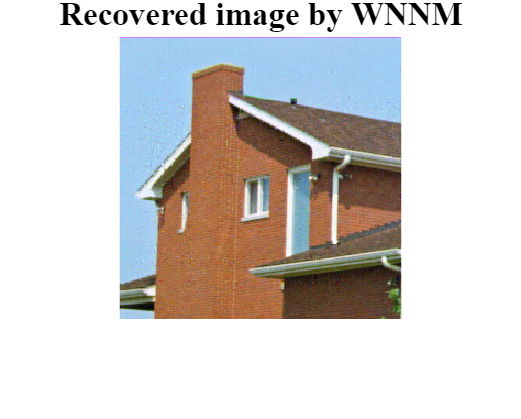

figure; imshow(wnnm_image,[]); title('Recovered image by WNNM','FontSize',15,'FontName','Times New Roman');

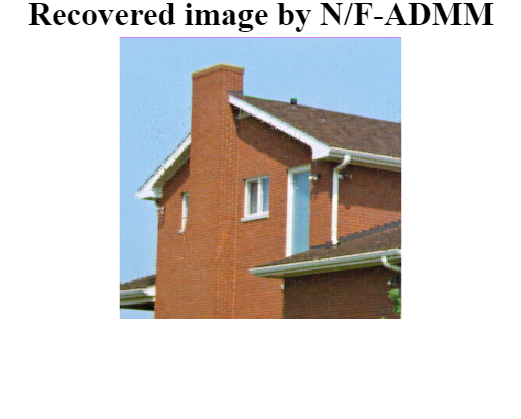

figure; imshow(nf_image, []); title('Recovered image by N/F-ADMM','FontSize',15,'FontName','Times New Roman');